# Trabajo Práctico 1: Ejercicio 3

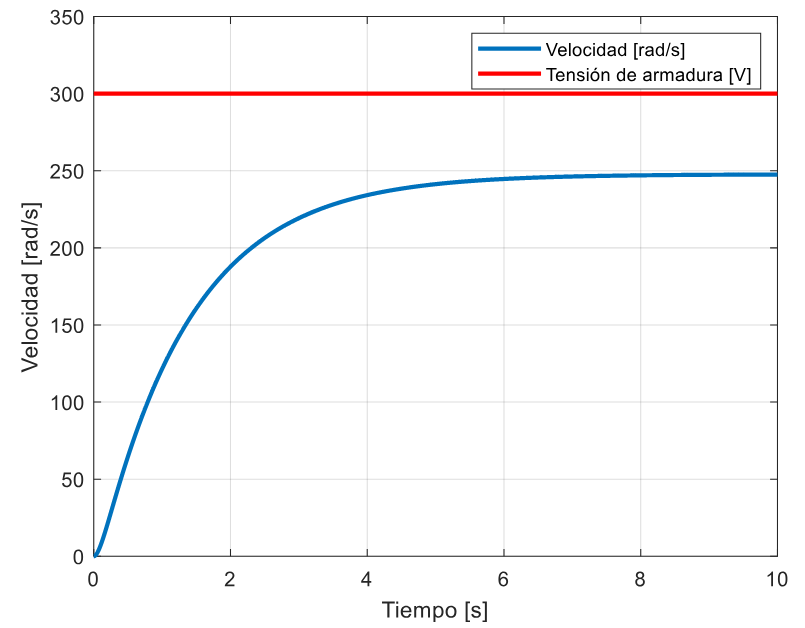

## Importar datos

clear

% Import data from text file
data = readtable("/home/fab/Documents/uni/control/2024/tps/tp1/ejercicio3/Velocidad _rad_s_.csv");

% Display results
data

data = 1000×2 table
    tiempo    velocidad
    ______    _________

     0.01            0 
     0.02      0.44757 
     0.03      0.89514 
     0.04       1.3427 
     0.05       2.6854 
     0.06       3.5806 
     0.07       4.0281 
     0.08       5.6748 
     0.09       6.9705 
      0.1       6.9705 
     0.11       8.5901 
     0.12       10.858 
     0.13       10.858 
     0.14       12.801 
     0.15       14.745 
     0.16       14.745 


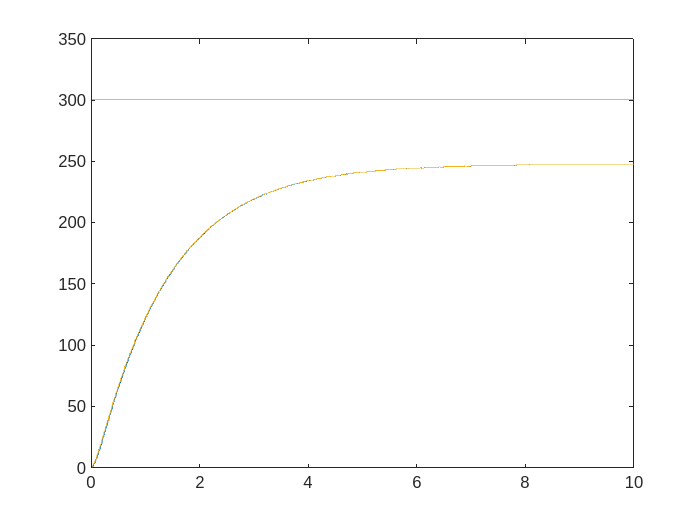

voltaje = 300 * ones(length(data.tiempo), 1);
plot(data.tiempo, [data.velocidad, voltaje]); hold on
% los datos verificar que los datos espaciados en el tiempo equitativamente
plot(linspace(0, 10, height(data)), data.velocidad)
hold off
ylim([0,350])

% si lo estan, entonces
tiempo = reshape(linspace(0, 10, height(data)), [], 1);
velocidad = data.velocidad;

## Punto A

Se trata de una función de segundo orden debido al comportamiento suave que se aprecia al inicio de la respuesta.

## Punto B

s = tf('s');
Kp = max(velocidad) / 300;

### Método de Ziegler-Nichols

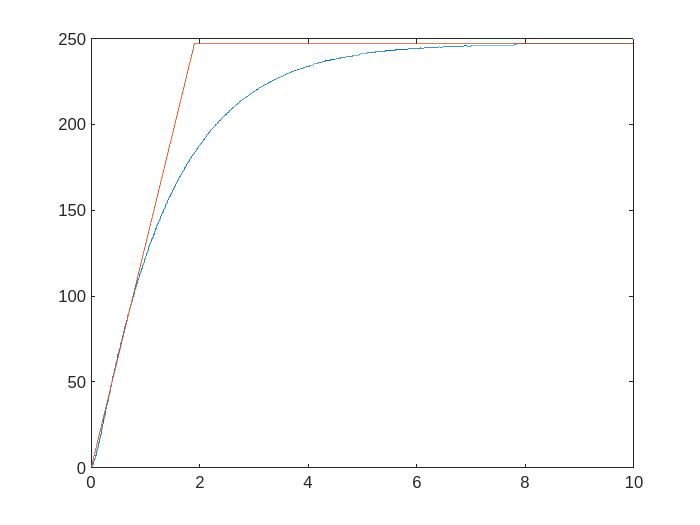

tope = 50; % valor a utilizar para cálculo de pendiente recta tangente:
for i = 1:height(velocidad)
    if velocidad(i) - tope < 0
        mZM_index = i;
    end 
end
m = (velocidad(mZM_index) - velocidad(1)) / (tiempo(mZM_index) - tiempo(1));
y_zm = m * tiempo;
for i = 1:height(velocidad)
    if y_zm(i) > max(velocidad)
        y_zm(i) = max(velocidad);
    end
end
plot(tiempo, [velocidad, y_zm])

tauZN_index = 1;
while y_zm(tauZN_index) ~= max(velocidad)
    tauZN_index = tauZN_index + 1;
end
tauZN = tiempo(tauZN_index);
thetaZN = 0;

tfZM = Kp * exp(-thetaZN * s) / (tauZN * s + 1)

tfZM =
 
    0.8244
  -----------
  1.912 s + 1
 
Continuous-time transfer function.
Model Properties


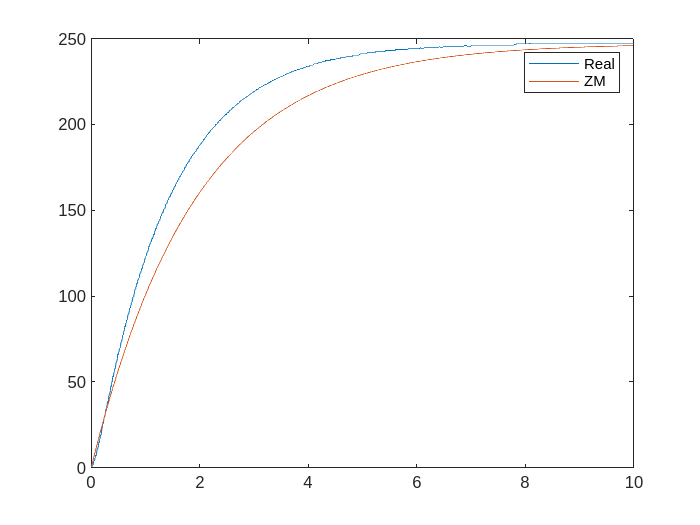

respuestaZN = lsim(tfZM, voltaje, tiempo);
plot(tiempo, [velocidad, respuestaZN])
legend(["Real", "ZM"])

### Método de Hägglund

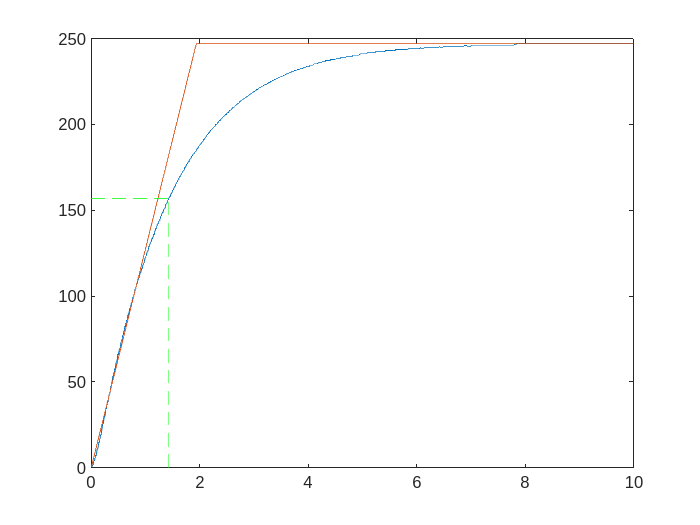

j = 100; % valor a utilizar para cálculo de pendiente recta tangente:
for i = 1:height(velocidad)
    if velocidad(i) - j < 0
        mHAG_index = i;
    end 
end
m = (velocidad(mHAG_index) - velocidad(1)) / (tiempo(mHAG_index) - tiempo(1));
y_hag = m * tiempo;
for i = 1:height(velocidad)
    if y_hag(i) > max(velocidad)
        y_hag(i) = max(velocidad);
    end
end

tauHAG_index = 1;
while velocidad(tauHAG_index) < 0.632*max(velocidad)
    tauHAG_index = tauHAG_index + 1;
end
tauHAG = tiempo(tauHAG_index);
thetaHAG = 0;

plot(tiempo, [velocidad, y_hag]); hold on
plot([tauHAG, tauHAG], [0, velocidad(tauHAG_index)], 'g--')
plot([0, tauHAG], [velocidad(tauHAG_index), velocidad(tauHAG_index)], 'g--')
hold off

tfHAG = Kp * exp(-thetaHAG * s) / (tauHAG * s + 1)

tfHAG =
 
    0.8244
  -----------
  1.431 s + 1
 
Continuous-time transfer function.
Model Properties


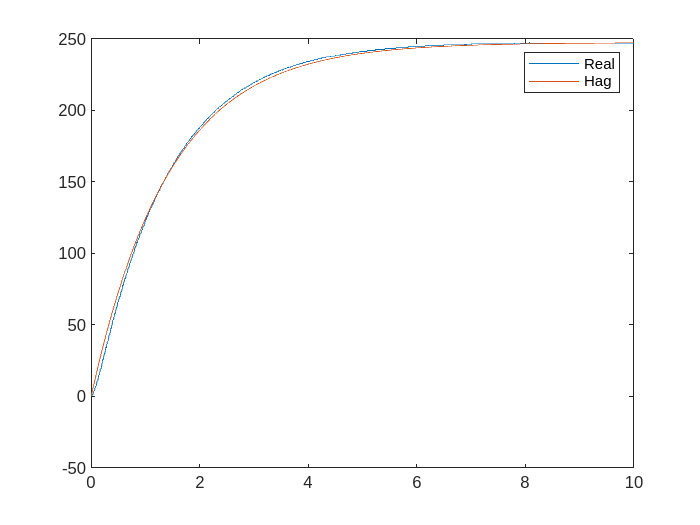

respuestaHAG = lsim(tfHAG, voltaje, tiempo);
plot(tiempo, [velocidad, respuestaHAG])
legend(["Real", "Hag"])

### Método de Sundaresan-Krishnaswamy

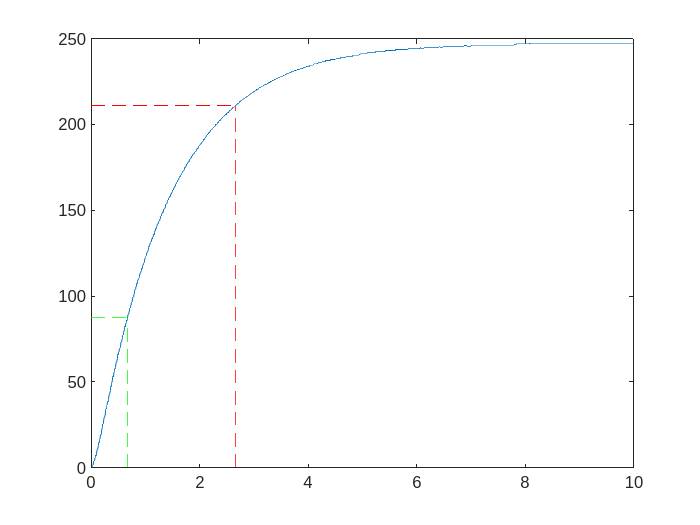

t1SK_index = 1;
while velocidad(t1SK_index) < 0.353*max(velocidad)
    t1SK_index = t1SK_index + 1;
end
t1SK = tiempo(t1SK_index);

t2SK_index = 1;
while velocidad(t2SK_index) < 0.853*max(velocidad)
    t2SK_index = t2SK_index + 1;
end
t2SK = tiempo(t2SK_index);

plot(tiempo, velocidad); hold on
plot([t1SK, t1SK], [0, velocidad(t1SK_index)], 'g--')
plot([0, t1SK], [velocidad(t1SK_index), velocidad(t1SK_index)], 'g--')
plot([t2SK, t2SK], [0, velocidad(t2SK_index)], 'r--')
plot([0, t2SK], [velocidad(t2SK_index), velocidad(t2SK_index)], 'r--')
hold off

tauSK = 0.67*(t2SK - t1SK);
thetaSK = 1.3 * t1SK - 0.29 * t2SK;
tfSK = Kp * exp(-thetaSK * s) / (tauSK * s + 1)

tfSK =
 
                     0.8244
  exp(-0.0997*s) * -----------
                   1.335 s + 1
 
Continuous-time transfer function.
Model Properties


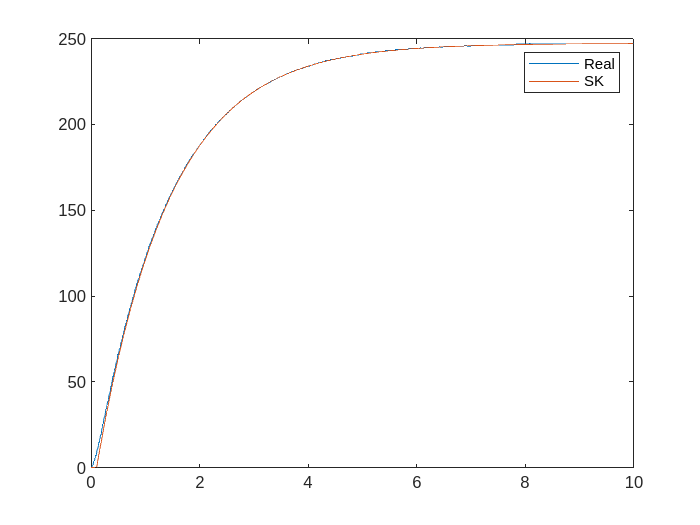

respuestaSK = lsim(tfSK, voltaje, tiempo);
plot(tiempo, [velocidad, respuestaSK])
legend(["Real", "SK"])

### Método de Stark–Mollenkamp

t15SM_index = 1;
while velocidad(t15SM_index) < 0.15*max(velocidad)
    t15SM_index = t15SM_index + 1;
end
t15SM = tiempo(t15SM_index);

t45SM_index = 1;
while velocidad(t45SM_index) < 0.45*max(velocidad)
    t45SM_index = t45SM_index + 1;
end
t45SM = tiempo(t45SM_index);

t75SM_index = 1;
while velocidad(t75SM_index) < 0.75*max(velocidad)
    t75SM_index = t75SM_index + 1;
end
t75SM = tiempo(t75SM_index);

xSM = (t45SM - t15SM) / (t75SM - t15SM);
xiSM = (0.0805 - 5.547*(0.475 - xSM)^2) / (xSM - 0.356);
f2SM = 2.6 * xiSM - 0.6;
nat_freqSM = f2SM / (t75SM - t15SM);
f3SM = 0.922*(1.66)^xiSM;
thetaSM = t45SM - (f3SM/nat_freqSM);
if thetaSM < 0 
    thetaSM = 0; % matlab control no puede utilizar theta menor a cero
end
tau1SM = (xiSM + sqrt(xiSM^2 - 1)) / (nat_freqSM);
tau2SM = (xiSM - sqrt(xiSM^2 - 1)) / (nat_freqSM);
tfSM = Kp * exp(-thetaSM * s) / ((tau1SM * s + 1) * (tau2SM * s + 1))

tfSM =
 
           0.8244
  -------------------------
  0.07514 s^2 + 1.397 s + 1
 
Continuous-time transfer function.
Model Properties


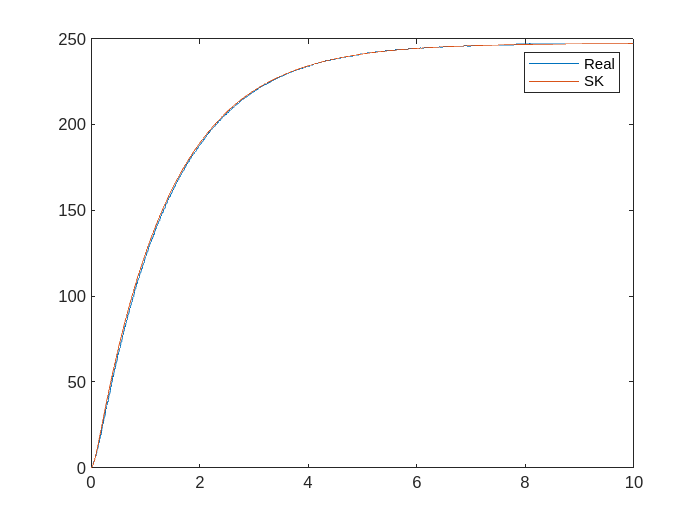

respuestaSM = lsim(tfSM, voltaje, tiempo);
plot(tiempo, [velocidad, respuestaSM])
legend(["Real", "SK"])

### Punto C

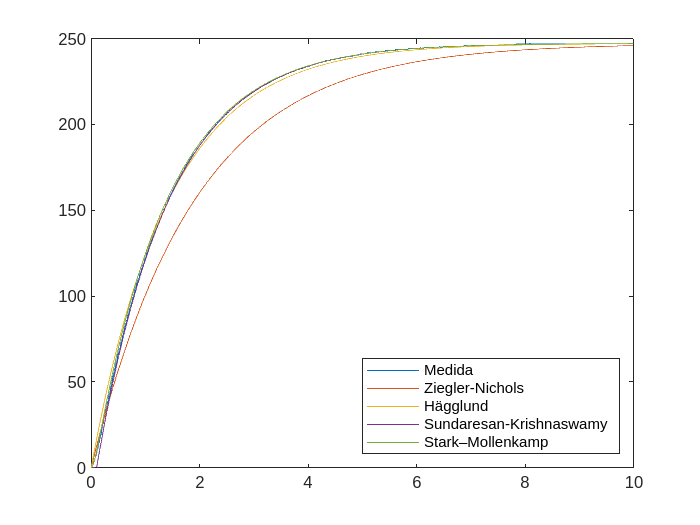

plot(tiempo, [velocidad, respuestaZN, respuestaHAG, respuestaSK, respuestaSM])
ylim([0,250])
legend('Medida', 'Ziegler-Nichols', 'Hägglund', 'Sundaresan-Krishnaswamy', 'Stark–Mollenkamp', "Location", 'southeast')

## Punto D

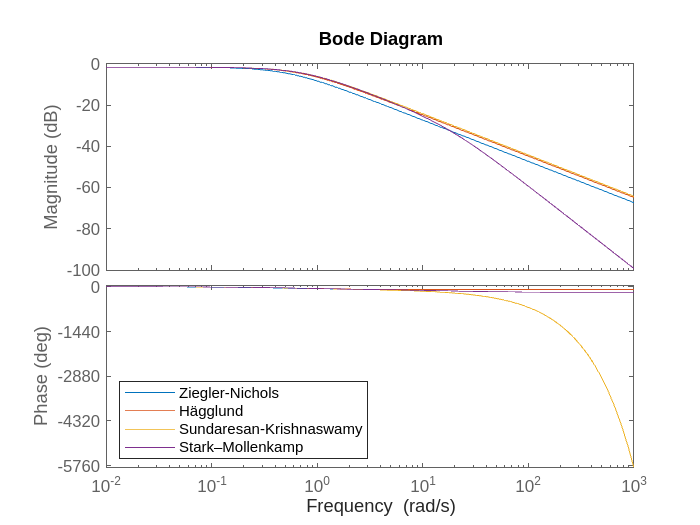

bode(tfZM); hold on 
bode(tfHAG)
bode(tfSK)
bode(tfSM); hold off
legend('Ziegler-Nichols', 'Hägglund', 'Sundaresan-Krishnaswamy', 'Stark–Mollenkamp', "Location", 'southwest')

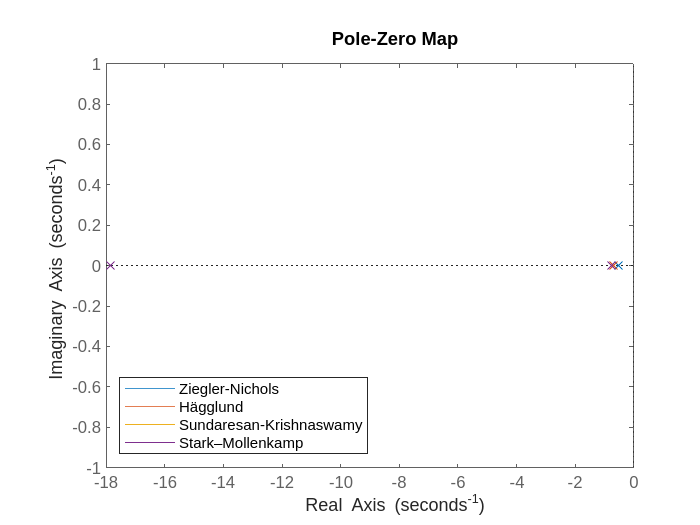

pzmap(tfZM); hold on 
pzmap(tfHAG)
pzmap(tfSK)
pzmap(tfSM); hold off
legend('Ziegler-Nichols', 'Hägglund', 'Sundaresan-Krishnaswamy', 'Stark–Mollenkamp', "Location", 'southwest')

## Punto E

### Integral del error de predicción absoluto

SEAP_ZN = sum(abs(velocidad-respuestaZN))

SEAP_ZN = 1.2095e+04

SEAP_HAG = sum(abs(velocidad-respuestaHAG))

SEAP_HAG = 1.5581e+03

SEAP_SK = sum(abs(velocidad-respuestaSK))

SEAP_SK = 465.0258

SEAP_SM = sum(abs(velocidad-respuestaSM))

SEAP_SM = 636.6887

### Integral del error de predicción cuadrático

SECP_ZN = sum((velocidad-respuestaZN).^2)

SECP_ZN = 2.2996e+05

SECP_HAG = sum((velocidad-respuestaHAG).^2)

SECP_HAG = 5.7235e+03

SECP_SK = sum((velocidad-respuestaSK).^2)

SECP_SK = 1.1897e+03

SECP_SM = sum((velocidad-respuestaSM).^2)

SECP_SM = 1.1922e+03